## [ARX Time Series Model](https://apmonitor.com/pds/index.php/Main/ARXTimeSeries)

An ARX model is a combination of an autoregressive model (AR) and an exogenous input model (X). It is used to represent the dynamics of a system and is commonly used in control engineering to model and analyze dynamic systems.

An autoregressive model is a type of statistical model that represents a time series as a linear combination of its past values and a stochastic process. It is represented by the following equation:


$$y\left(t\right)=c+a_1 y\left(t-1\right)+a_2 y\left(t-2\right)+\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp +a_p y\left(t-p\right)+e\left(t\right)$$


where *y(t)* is the value of the time series at time *t*, *c* is a constant term, *a**1*, *a**2*, ..., *a**p* are the autoregressive coefficients, *y(t-1)*, *y(t-2)*, ..., *y(t-p)* are the past values of the time series, and *e(t)* is a random error term.

An exogenous input model represents a time series as a linear combination of its past values and a set of exogenous (i.e., external) input variables. It is represented by the following equation:


$$y\left(t\right)=c+b_1 u_1 \left(t\right)+b_2 u_2 \left(t\right)+\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp +b_q u_q \left(t\right)+e\left(t\right)$$


where *y(t)* is the value of the time series at time *t*, *c* is a constant term, *u**1**(t)*, *u**2**(t)*, ..., *u**q**(t)* are the exogenous input variables, and *b**1*, *b**2*, ..., *b**q* are the coefficients that capture the relationship between the input variables and the output.

An ARX model is a combination of an AR model and an X model, and it is represented by the following equation:


$$y\left(t\right)=c+a_1 y\left(t-1\right)+a_2 y\left(t-2\right)+\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp +a_p y\left(t-p\right)+b_1 u_1 \left(t\right)+b_2 u_2 \left(t\right)+\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp +b_q u_q \left(t\right)+e\left(t\right)$$


ARX time series models are a linear representation of a dynamic system in discrete time. Putting a model into ARX form is the basis for many methods in process dynamics and control analysis. Below is the time series model with a single input and single output with *k* as an index that refers to the time step.


$$y_{k+1} =\sum_{i=1}^{n_a } a_i y_{k-1+1} +\sum_{i=1}^{n_b } b_i u_{k-1+1}$$


With *n**a*=3, *n**b*=2, *n**u*=1, and *n**y*=1 the time series model is:


$$y_{k+1} =a_1 y_k +a_2 y_{k-1} +a_3 y_{k-2} +b_1 u_k +b_2 u_{k-1}$$


There may also be multiple inputs and multiple outputs such as when *n**a*=1, *n**b*=1, *n**u*=2, and *n**y*=2.


$${\textrm{y1}}_{k+1} =a_{1,1} {\;\;\textrm{y1}}_k \;+b_{1,1\;} {\textrm{u1}}_k +b_{1,2} \;{\textrm{u2}}_k$$



$${\mathrm{y2}}_{k+1} =a_{1,2} {\;\mathrm{y2}}_k +b_{2,1} \;{\mathrm{u1}}_k +b_{2,2\;} {\mathrm{u2}}_k$$


Time series models are used for identification and advanced control. It has been in use in the process industries such as chemical plants and oil refineries since the 1980s. Model predictive controllers rely on dynamic models of the process, most often linear empirical models obtained by system identification.

# System Identification Toolbox Method 

%%%%Retrieve Data for Timetable (tt)
url = 'http://apmonitor.com/do/uploads/Main/tclab_dyn_data2.txt'

url = 'http://apmonitor.com/do/uploads/Main/tclab_dyn_data2.txt'

websave('data_arx', url);
arx_data = readtable('data_arx');
%%%Extract time
tt = arx_data.Time

tt =      0
     1
     2
     3
     4
     5
     6
     7
     8
     9



%%%% Create coefficents for the ARX model  
A = [1, 0.36788, 0.36788];
B = [0, 0.63212, 0.31606];
%B = transpose(B);
%%%%A - ;0.223,-0.136
%%%B - ; 0.18964,1.26420

sys0 = idpoly(A,B);
u = iddata([],idinput(300,'rbs'));
e = iddata([],randn(300,1));
y = sim(sys0,[u e]);
z = [y,u];




%%%% system identification parameters
na = 3 %% output coefficients

na = 3

nb = 2 %% input coefficients

nb = 2

nk = 1

nk = 1


sys = arx(z,[na nb nk])

sys =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
  A(z) = 1 + 0.439 z^-1 + 0.2981 z^-2 - 0.0208 z^-3
                                                   
  B(z) = 0.6127 z^-1 + 0.3741 z^-2                 
                                                   
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=3   nb=2   nk=1
   Number of free coefficients: 5
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                         
Estimated using ARX on time domain data "sys0". 
Fit to estimation data: 25.1% (prediction focus)
FPE: 0.818, MSE: 0.7755                         
 
Model Properties



%%%% Plot arx model created 
%%%%QUESTION: is it possible to graph 


sys_nl = nlarx(z,[na nb nk])

sys_nl =

Nonlinear ARX model with 1 output and 1 input
  Inputs: u1
  Outputs: y1

Regressors:
  Linear regressors in variables y1, u1
  List of all regressors

Output function: Wavelet network with 1 units
Sample time: 1 seconds

Status:                                          
Estimated using NLARX on time domain data "sys0".
Fit to estimation data: 25.74% (prediction focus)
FPE: 0.8072, MSE: 0.7623                         
More information in model's "Report" property.



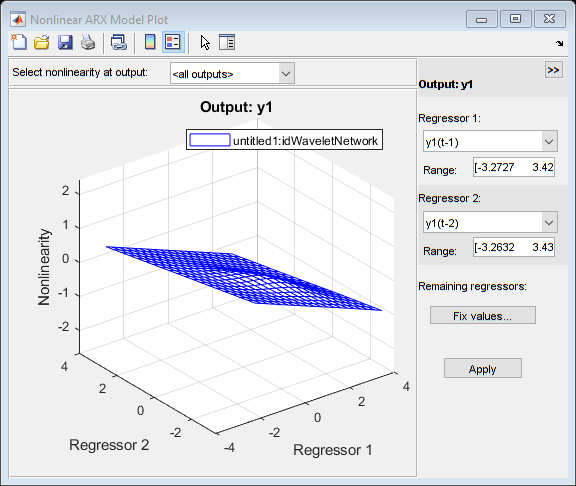

nlarxPlot(sys_nl)

# Utilizing Python Gekko Package

import matlab.*
import numpy.*

nf = numpy.array([[1.1, 2,2, 3.3], [4.4, 5.5, 6.6]])
md = matlab.double(nf)
ni32 = numpy.array([[1, 2, 3], [4, 5, 6]], dtype='int32')
mi32 = matlab.int32(ni32)


py.gekko

Unrecognized method, property, or field 'gekko' for class 'matlab.pyclient.PythonEnvironment'.